# *Homework 5*

#### *Grant Roberts*

#### *11/11/2018*

## *Introduction*

In this MATLAB exercise we will investigate the phase of images acquired in a phantom and in vivo in respect to the echo time in a spoiled gradient echo sequence (aka SPGR aka FLASH). We will generate frequency maps and images that separate water and fat based on Dixon reconstruction techniques. The lecture slides on this topic should provide a solid basis for the analysis at hand. In addition, a write-up from Dr. John Pauly at Stanford University is provided.

**Please label all images properly: provide colorbars and a title. Also provide labels for x and y when you see it necessary. Make sure that the images are properly displayed in terms of their aspect ratio (hint: use truesize with imshow or axis image)**

## *Problem 1 -- Phantom Data*

Read the phantom data set into Matlab. In this experiment, I placed 1 vial of fat on top of 2 vials of water. Those are single slice data that were acquired with a gradient echo sequence on a Siemens Sonata scanner. The TR was kept constant at 40 ms while the echo time TE was shifted from 4.0 ms (Series 01) to 6.0 ms (Series 02) and 8.0 ms (Series 03) corresponding to in and out of phase images or water and fat.

Note the difference in raw data format from the GE datasets that were provided in Homework #2. For each Series, there is a data file (meas.out) and a text file (meas.asc). The text file contains details on the scan parameters (e.g. field of view, bandwidth, etc).

## 1a) 

**Find the parameters for field of view and slice thickness in in the scan parameter file for Series 1 and report the values** (sSliceArray.asSlice[0].dThickness, sSliceArray.asSlice[0].dPhaseFOV, sSliceArray.asSlice[0].dReadoutFOV = 300 – all stored in mm). 

Tip: If you **change the extension of meas.asc to meas.txt**, your computer will associate the appropriate text editor with opening this file.

%%% Setup
close all

cd('../..')
% hw5dir = 'C:\Users\groberts\Documents\Fall 2018 Classwork\MP710\Homework\MP710_HW5_Files';
hw5dir = 'C:\Users\robertsgr\Documents\MP710\Homework\MP710_HW5_Files';
cd(hw5dir);                         % Start at home
addpath(genpath('.'))               % Add all subfolders to path

%%% Find parameters
cd('Data_Phantom')

% Convert all .asc files to .txt
DIR = dir('./*/*.asc');
for ii=1:length(DIR)
    filename = DIR(ii).name;
    cd(DIR(ii).folder)
    [pathstr, name, ext] = fileparts([DIR(ii).folder '\' filename]);
    copyfile(filename, fullfile(pathstr, [name, '.txt']));
end

%Read text file
cd('../01')
fileID = fopen('meas.asc');
Info = strtrim(textscan(fileID,'%s %s','Delimiter','='));
fclose(fileID);  

%Find specific values in text file
% This uses "lookup", a function defined at the end of this script.
% Lookup finds the value associated with a field.
field = Info{1}; value = Info{2};  
dZ = lookup(field,value,'sSliceArray.asSlice[0].dThickness',1);
FOVx = lookup(field,value,'sSliceArray.asSlice[0].dReadoutFOV',1);
FOVy = lookup(field,value,'sSliceArray.asSlice[0].dPhaseFOV',1);
TE = [4 6 8]; %ms

formatSpec = 'FOVx = %d mm, FOVy = %d mm, Slice thickness = %d mm';
sprintf(formatSpec,FOVx,FOVy,dZ)

ans = 'FOVx = 300 mm, FOVy = 300 mm, Slice thickness = 10 mm'

## 1b) 

**Read the raw k-space data into Matlab **and generate the corresponding images for each echo time. I prepared a routine read_raw_form_n4.m to read the data and I also posted a mini script script_read_phantom.m to show you how to use it. **Provide the resulting images (magnitude and phase) for all 3 echoes.**

%Read phantom data
script_read_phantom


Read image volume: 256 x 256 x 3


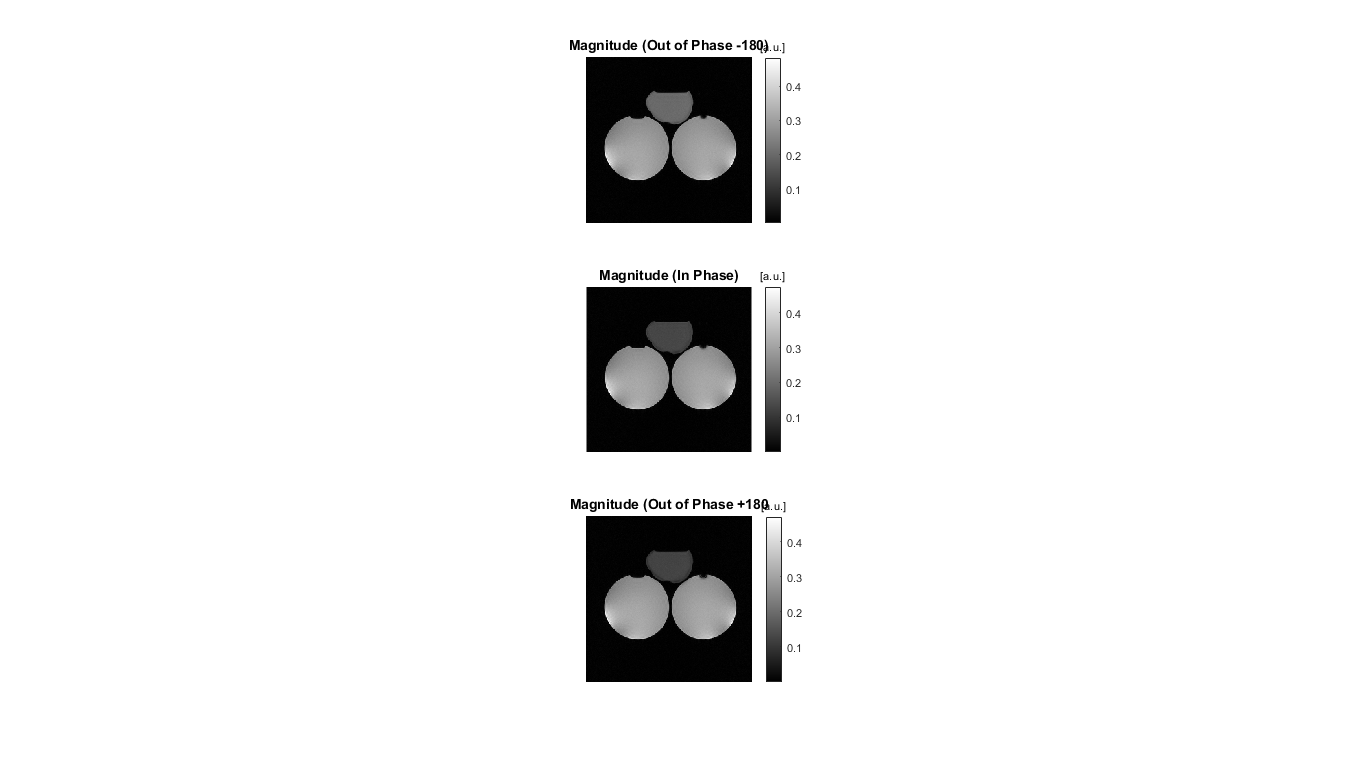

im = im_vol; clear im_vol;
mag = abs(im);
phase = angle(im);

% % Magnitude
fullfig; subplot(3,1,1); imshow(mag(:,:,1),[]);  title('Magnitude (Out of Phase -180)'); colorbar; map1 = colorbar; title(map1,'[a.u.]');
subplot(3,1,2); imshow(mag(:,:,2),[]);  title('Magnitude (In Phase)'); colorbar; map2 = colorbar; title(map2,'[a.u.]');
subplot(3,1,3); imshow(mag(:,:,3),[]);  title('Magnitude (Out of Phase +180'); colorbar; map3 = colorbar; title(map3,'[a.u.]');

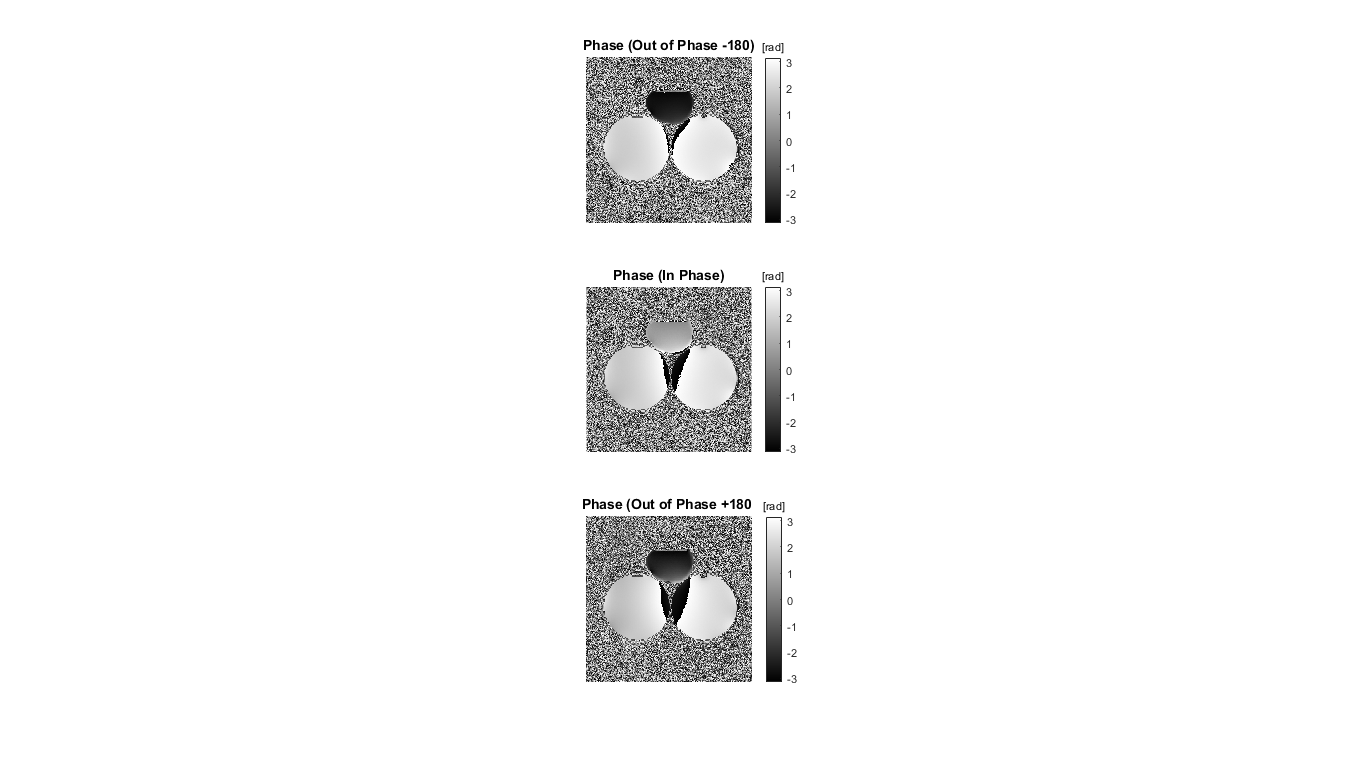


% Phase
fullfig; subplot(3,1,1); imshow(phase(:,:,1),[]);  title('Phase (Out of Phase -180)'); colorbar; map1 = colorbar; title(map1,'[rad]');
subplot(3,1,2); imshow(phase(:,:,2),[]);  title('Phase (In Phase)'); colorbar; map2 = colorbar; title(map2,'[rad]');
subplot(3,1,3); imshow(phase(:,:,3),[]);  title('Phase (Out of Phase +180 '); colorbar; map3 = colorbar; title(map3,'[rad]');

## 1c)

**Draw regions of interest in each of the 3 vials and create plots of signal vs echo time and phase vs echo time**. Remember that phase wraps may occur and try to compensate for those. **Describe the results**.

% Mask
mask1 = mag(:,:,1);
for i =1:size(mag,1)
    for j = 1:size(mag,2)
        if mask1(i,j) < 0.05  %Thresholding arbitrary value from mag images
            mask1(i,j) = 0;  
        else 
            mask1(i,j) = 1;
        end
    end
end

Vial #1 - Far Left

%Draw ROI's for each vial.
fullfig; subplot(3,1,1);
imshow(mag(:,:,1),[]);
ROI1 = drawrectangle('Color','g','Label','ROI1');
title('Vial #1 (Far Left)');
i1 = floor(ROI1.Position);          % Position of the ROI [xmin, ymin, width, height]
                                    % xmin and ymin = upper left corner of ROI
rows1 = i1(2):(i1(2)+i1(4));
cols1 = i1(1):(i1(1)+i1(3));

% The signal will be averaged over the ROI for magnitude and phase images.
S1mag = zeros(1,3);
for ii=1:3
    S1mag(ii) = mean2(mag(rows1,cols1,ii)); % Get mean for each time frame
end
S1phase = zeros(1,3);
for ii=1:3
    S1phase(ii) = mean2(phase(rows1,cols1,ii)); % Get mean for each time frame
end

Vial #2 - Upper-Middle 

subplot(3,1,2);
imshow(mag(:,:,1),[]);
ROI2 = drawrectangle('Color','g','Label','ROI2');
title('Vial #2 (Upper Middle)');
i2 = floor(ROI2.Position);          % Position of the ROI [xmin, ymin, width, height]
                                    % xmin and ymin = upper left corner of ROI
rows2 = i2(2):(i2(2)+i2(4));
cols2 = i2(1):(i2(1)+i2(3));

% The signal will be averaged over the ROI for magnitude and phase images.
S2mag = zeros(1,3);
for ii=1:3
    S2mag(ii) = mean2(mag(rows2,cols2,ii)); % Get mean for each time frame
end
S2phase = zeros(1,3);
for ii=1:3
    S2phase(ii) = mean2(phase(rows2,cols2,ii)); % Get mean for each time frame
end

Vial #3 - Far Right

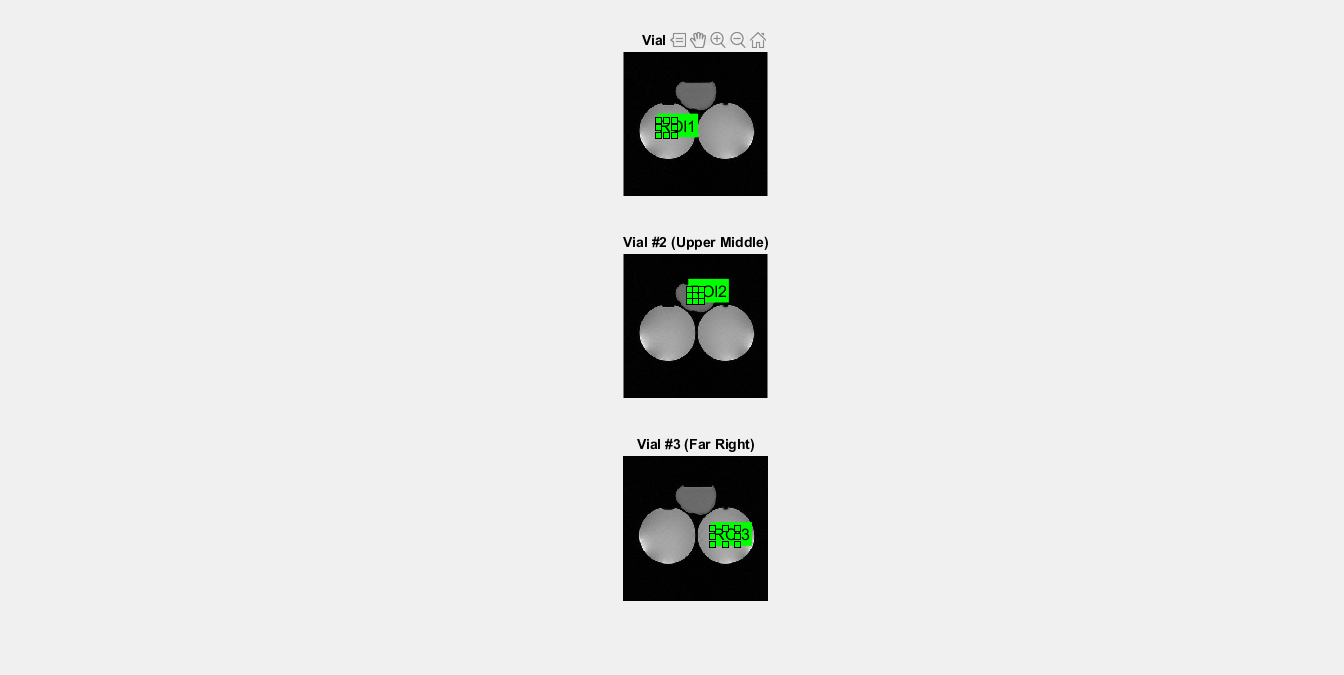

subplot(3,1,3);
imshow(mag(:,:,1),[]);
ROI3 = drawrectangle('Color','g','Label','ROI3');
title('Vial #3 (Far Right)');

i3 = floor(ROI3.Position);          % Position of the ROI [xmin, ymin, width, height]
                                    % xmin and ymin = upper left corner of ROI
rows3 = i3(2):(i3(2)+i3(4));
cols3 = i3(1):(i3(1)+i3(3));

% The signal will be averaged over the ROI for magnitude and phase images.
S3mag = zeros(1,3);
for ii=1:3
    S3mag(ii) = mean2(mag(rows3,cols3,ii)); % Get mean for each time frame
end
S3phase = zeros(1,3);
for ii=1:3
    S3phase(ii) = mean2(phase(rows3,cols3,ii)); % Get mean for each time frame
end


Plot means of each ROI for each frame

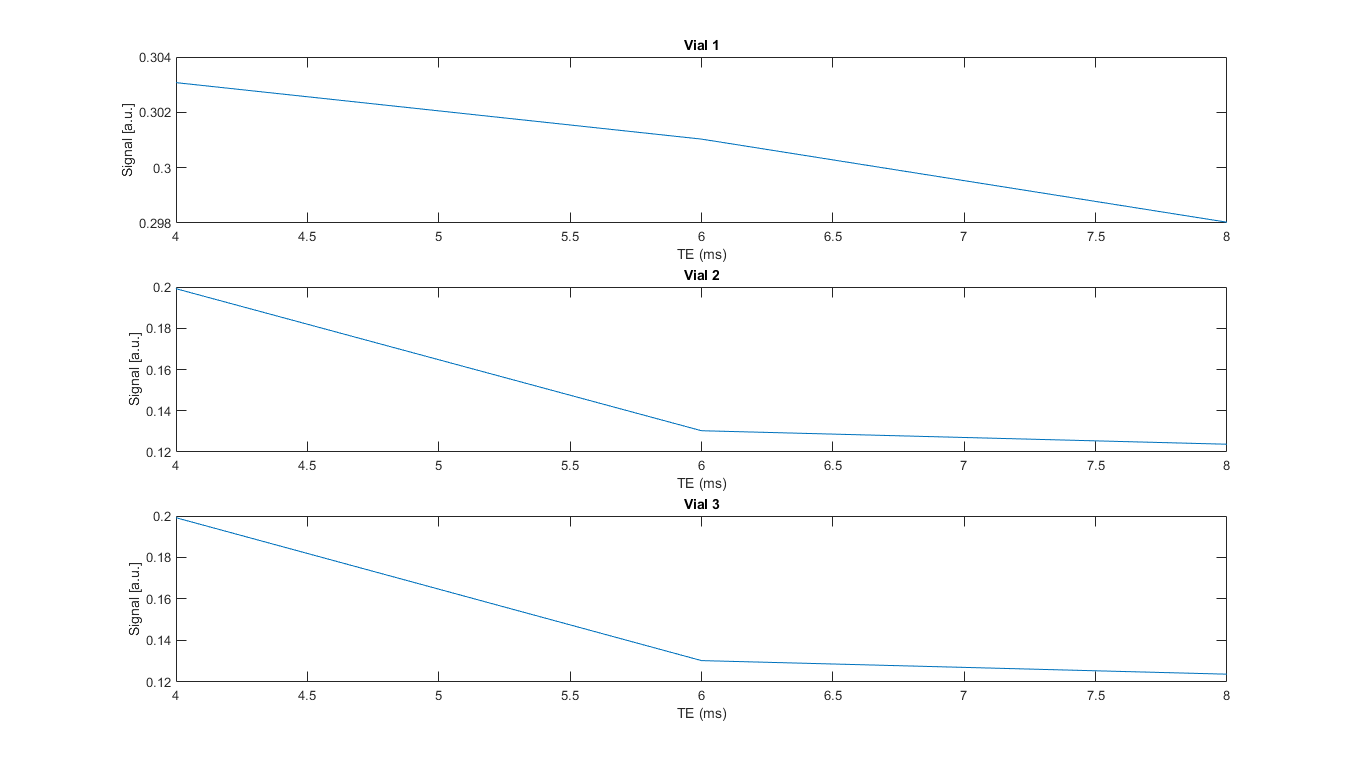

% Magnitude
fullfig;
subplot(3,1,1)
plot(TE,S1mag)
title('Vial 1'); xlabel 'TE (ms)'; ylabel 'Signal [a.u.]';
subplot(3,1,2)
plot(TE,S2mag)
title('Vial 2'); xlabel 'TE (ms)'; ylabel 'Signal [a.u.]';
subplot(3,1,3)
plot(TE,S2mag)
title('Vial 3'); xlabel 'TE (ms)'; ylabel 'Signal [a.u.]';

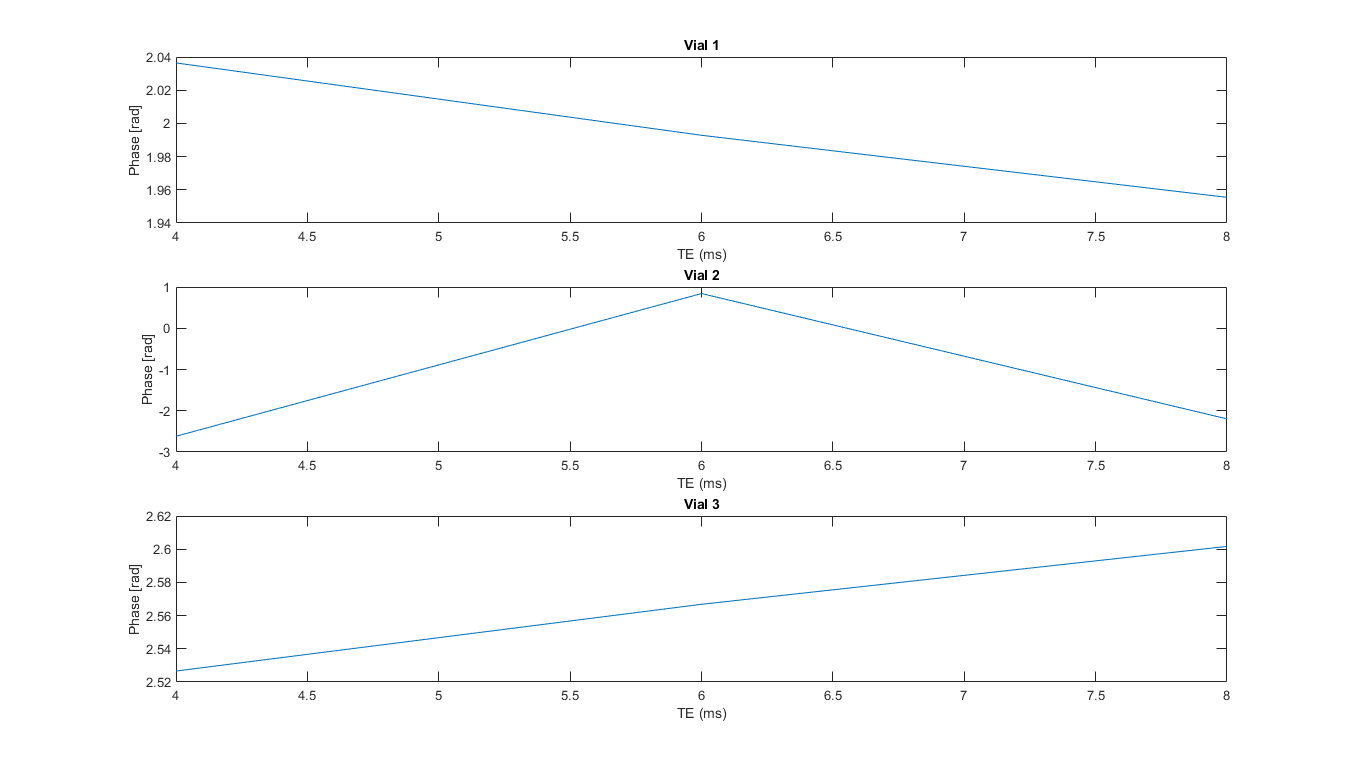


%Phase
fullfig;
subplot(3,1,1)
plot(TE,S1phase)
title('Vial 1'); xlabel 'TE (ms)'; ylabel 'Phase [rad]';
subplot(3,1,2)
plot(TE,S2phase)
title('Vial 2'); xlabel 'TE (ms)'; ylabel 'Phase [rad]';
subplot(3,1,3)
plot(TE,S3phase)
title('Vial 3'); xlabel 'TE (ms)'; ylabel 'Phase [rad]';

## 1d)

Implement a 2-point Dixon reconstruction. **Provide the water only and a fat only image of the phantom**.

The 2-point dixon method assumes perfect field homogeneity, that fat has only 1 pure spectral component, and that the images were acquired perfectly in phase (IP) and out of phase (OP).

For the simple 2-point Dixon:

    Water = 1/2(IP + OP)

    Fat = 1/2(IP - OP)

We can further correct for the $\phi_{0\;}$ off-resonance factor by taking the absolute value of the sum of the fat and water contributions. This effectively gits rid of the initial phase offset caused by local RF penetration issues and delays in the receiver chains in the coils. This, however, still does not fix off-resonance from field homogeneity.

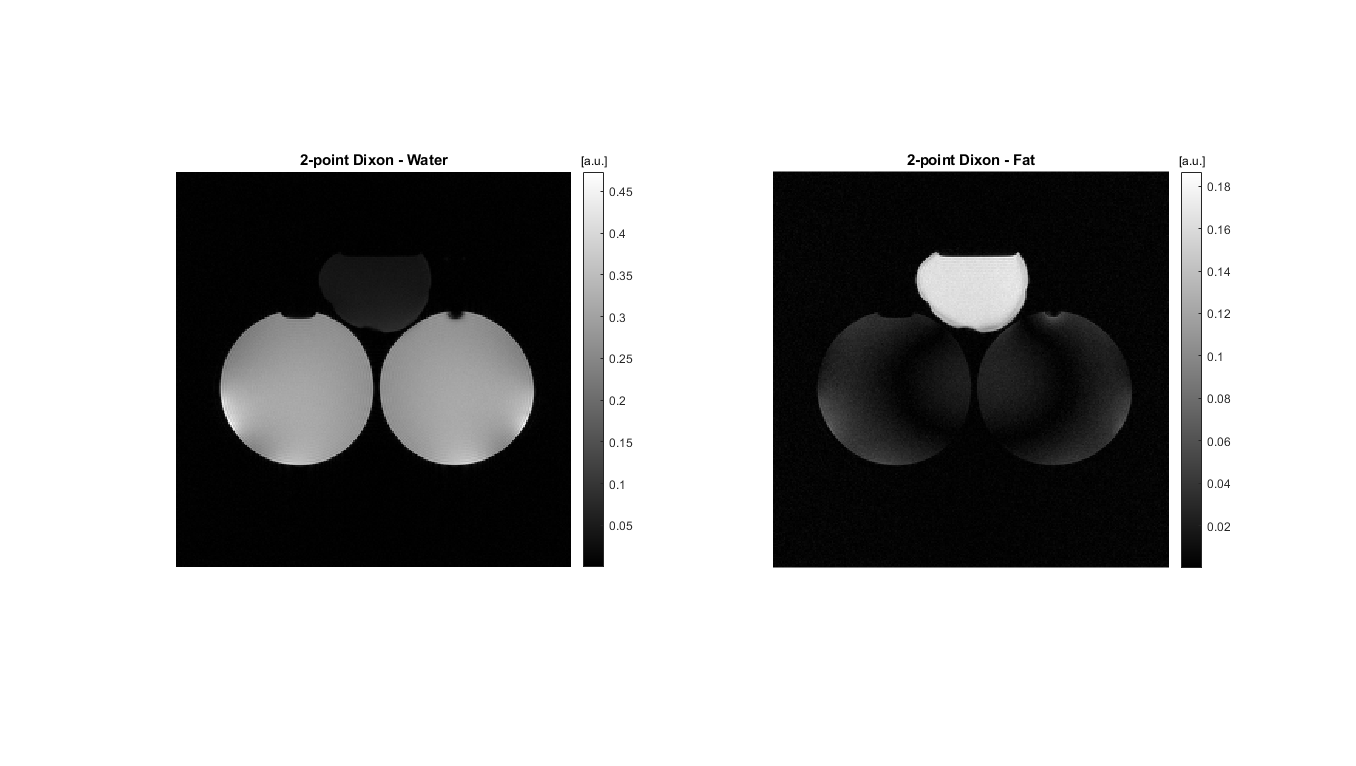

IP = im(:,:,2); %In phase
OP = im(:,:,1); %Opposed phase (-180)
OP_ = im(:,:,3); %Opposed phase (+180)

water = 0.5*abs(IP + OP);
fat = 0.5*abs(IP - OP);
fullfig; subplot(1,2,1); imshow(water,[]);  title('2-point Dixon - Water'); colorbar; map1b = colorbar; title(map1b,'[a.u.]');
subplot(1,2,2); imshow(fat,[]); title('2-point Dixon - Fat'); colorbar; map2b = colorbar; title(map2b,'[a.u.]');

## 1e)

Implement a modified 2-point Dixon reconstruction. **Provide the water only and a fat only image of the phantom.**

In the modified Dixon method, we synthesize the third 3-point Dixon measurement from only two echoes. 

To synthesize the off-resonance factor, we can use the following formula:


$$2\phi^ˆ =\angle {\left(m_1^* m_2 \right)}^2$$


And apply it to the equations:


$$\hat{m_w } =\frac{1}{2}\left(m_w \left(1+e^{i\phi \;} \right)+m_f \left(1-e^{i\phi \;} \right)\right)$$



$$\hat{m_f } =\frac{1}{2}\left(m_w \left(1-e^{i\phi \;} \right)+m_f \left(1+e^{i\phi \;} \right)\right)$$


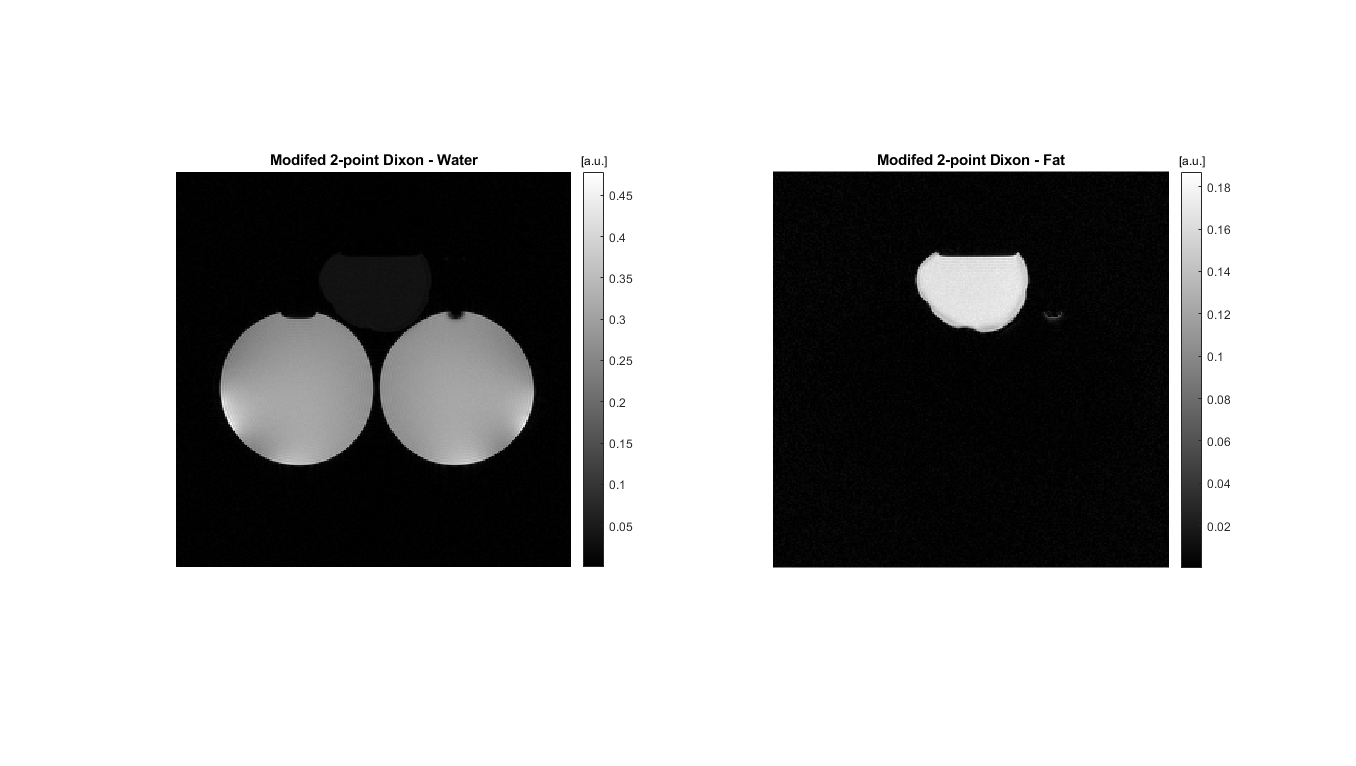

phi_hat1 = 0.5*angle((conj(IP).*OP).^2);
water2 = 0.5*abs((IP + OP.*exp(-1i*phi_hat1)));
fat2 = 0.5*abs((IP - OP.*exp(-1i*phi_hat1)));

fullfig; subplot(1,2,1); imshow(water2,[]);  title('Modifed 2-point Dixon - Water'); colorbar; map1c = colorbar; title(map1c,'[a.u.]');
subplot(1,2,2); imshow(fat2,[]); title('Modifed 2-point Dixon - Fat'); colorbar; map2c = colorbar; title(map2c,'[a.u.]');

## 1f)

Implement a 3-point Dixon reconstruction.** Provide the water only and a fat only image and the field map of the phantom.**

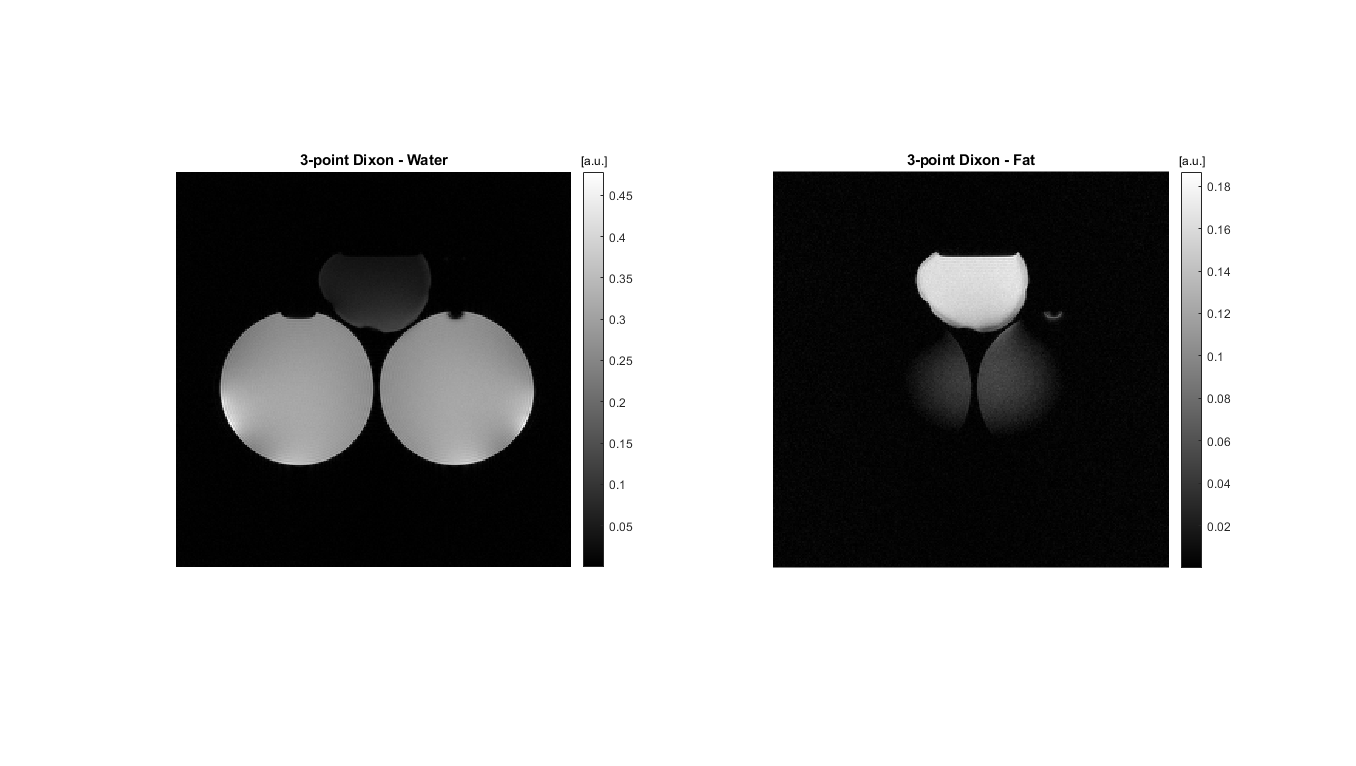

IP_temp = IP.*mask1;
OP_temp = OP.*mask1;

phi_hat2 = 0.5*abs((angle(conj(OP).*OP_)));
water3 = 0.5*abs((IP + OP.*exp(-1i*phi_hat2)));
fat3 = 0.5*abs((IP - OP.*exp(-1i*phi_hat2)));


fullfig; subplot(1,2,1); imshow(water3,[]);  title('3-point Dixon - Water'); colorbar; map1 = colorbar; title(map1,'[a.u.]');
subplot(1,2,2); imshow(fat3,[]); title('3-point Dixon - Fat'); colorbar; map2 = colorbar; title(map2,'[a.u.]');

## 1g)

Field Map Estimation: The phase estimate φ (in radians) can be converted to a frequency estimate (in Hz) by dividing φ by 2π ΔTE, where ΔTE is the time between the first and second images. **Generate and provide the field map.**

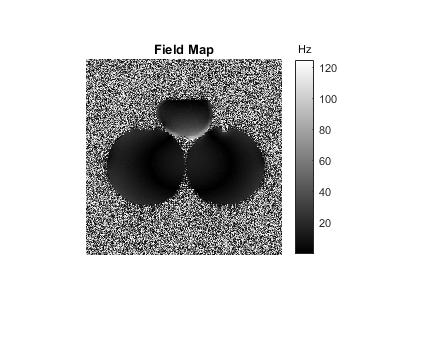

dT = 0.002;
% Phase offset (calculated above) shows precessional differences over a TE.
field_map = (phi_hat2)/(2*pi*dT);
fullfig; imshow(field_map,[]); title('Field Map'); colorbar; map = colorbar; title(map,'Hz');

The largest susceptibility artifacts (resultant from inhomogenity) are near the bottom of the fat vial. This is most likely due to the sharp changes in material interfaces (air and water), which often result in susceptibility artifacts, such as bone-air interfaces that result in susceptibility artifact in the skull. There is also slowly varying inhomogeneity across all vials.

## 1h)

**Compare the results from d, e, and f.**

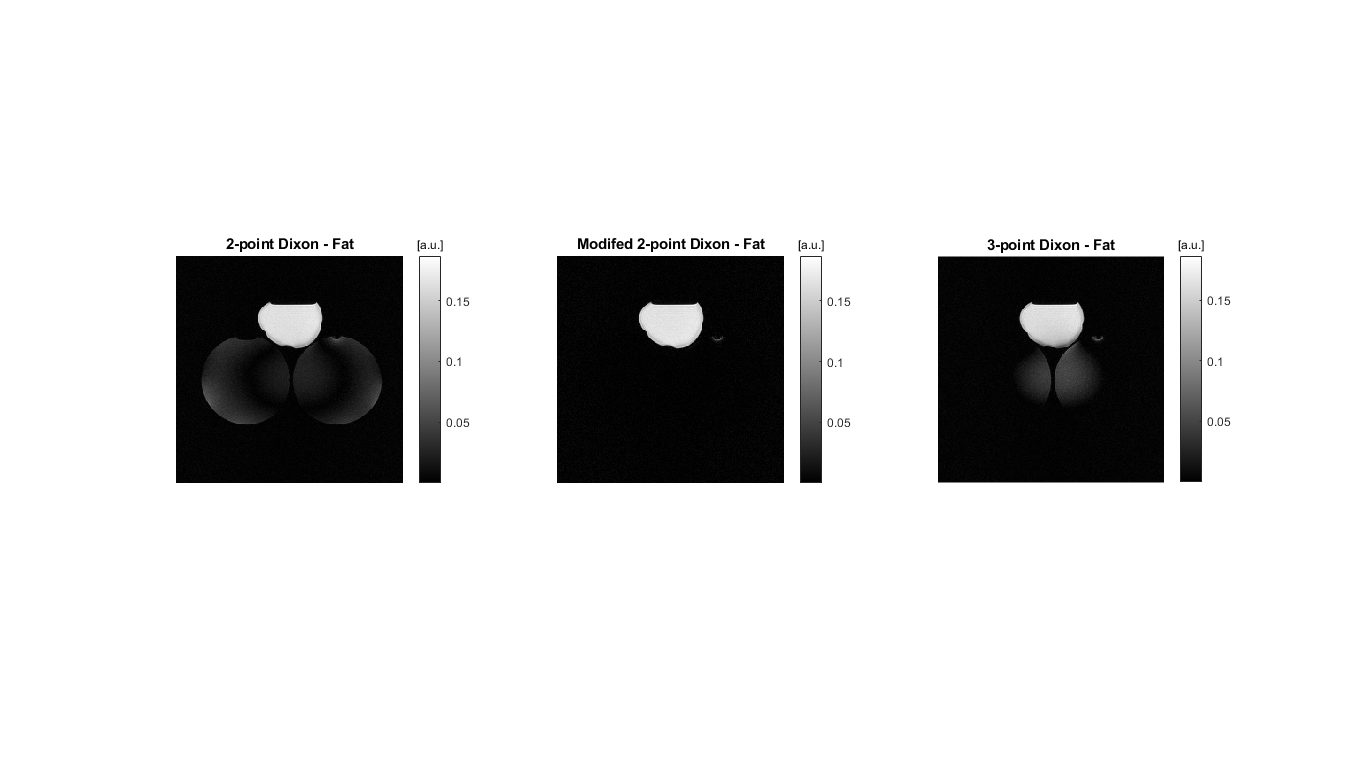

fullfig; subplot(1,3,1); imshow(fat,[]); title('2-point Dixon - Fat'); colorbar; map2a = colorbar; title(map2a,'[a.u.]');
subplot(1,3,2); imshow(fat2,[]);  title('Modifed 2-point Dixon - Fat'); colorbar; map2b = colorbar; title(map2b,'[a.u.]');
subplot(1,3,3); imshow(fat3,[]); title('3-point Dixon - Fat'); colorbar; map2c = colorbar; title(map2c,'[a.u.]');

Of the three methods, the modified 2-point method seems to be superior. If phase-unwrapping had been applied to the 3-point Dixon, we would likely see better results. The simple 2-point does not completely git rid of the water signal in the fat image. This is due to off-resonance effects discusses in the Pauly Lecture.

## *Problem 2 -- In Vivo Data*

The in vivo data set was provided by Dr. John Pauly from Stanford University. It is saved in matlab format in the file dixon_images.mat. There are three matlab variables, image 1, image 2, and image 3, which contain the three Dixon images. The images are from a gradient recalled sequence, with echo times of 12.8 ms, 19.2 ms, and 25.6 ms. These correspond to 2π, 3 π and 4 π phase shifts of the fat/water difference frequency, which is 72 Hz for 0.5T where these images were acquired. Before starting, take a look at the three images to get a sense of the different information they contain. The first and third have water and fat in phase, while water and fat have opposing phase in the second image. This is particularly noticeable behind the eye in the contrast between the optic nerve (water) and the retro-orbital fat.

## 1a)

**Run the 3 reconstructions developed in problem 1 (2-point Dixon, 2-point modified Dixon and 3-point Dixon) and compare the results.**

cd('../..')
load('dixon_images.mat')
img1 = image_1;
img2 = image_2;
img3 = image_3;

2-point Dixon reconstruction.

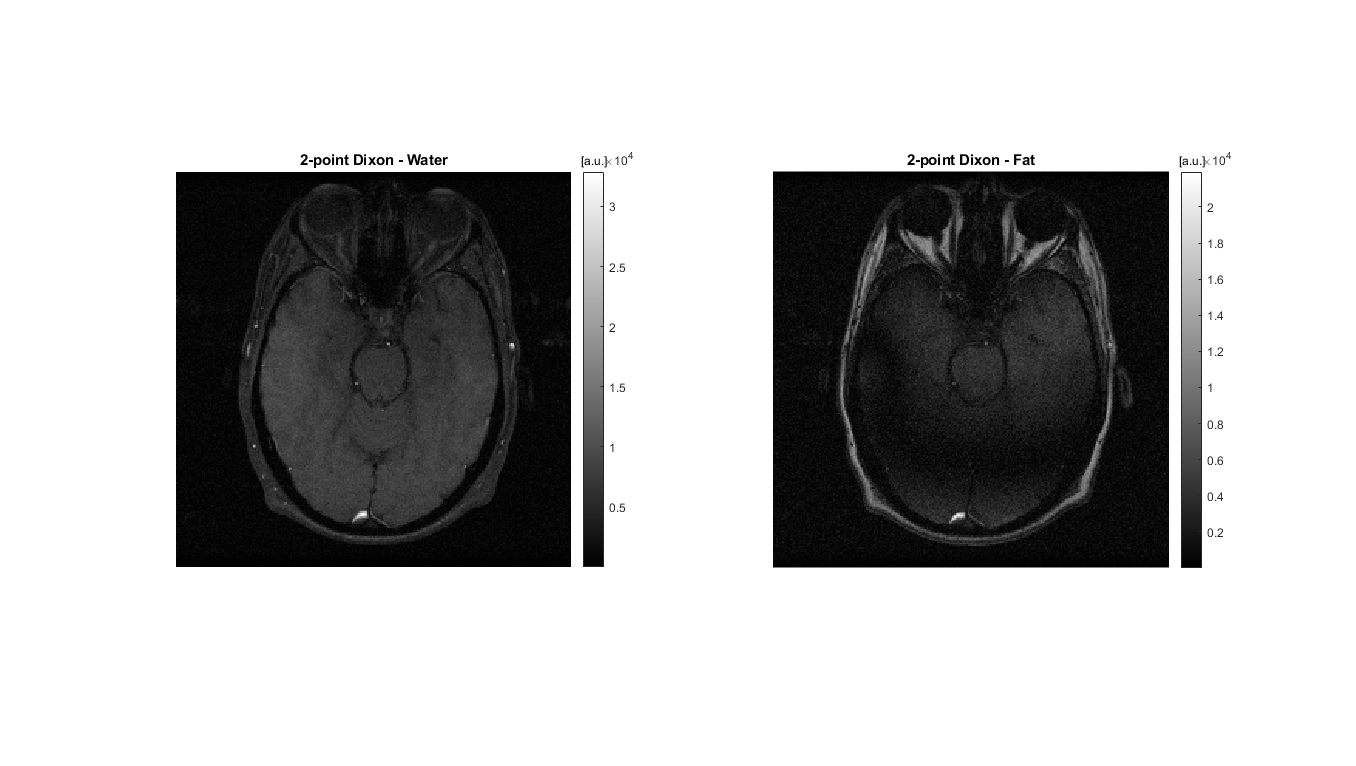

Water = 0.5*abs(img2+img1);
Fat = 0.5*abs(img2-img1);
fullfig; subplot(1,2,1); imshow(Water,[]);  title('2-point Dixon - Water'); colorbar; map1b = colorbar; title(map1b,'[a.u.]');
subplot(1,2,2); imshow(Fat,[]); title('2-point Dixon - Fat'); colorbar; map2b = colorbar; title(map2b,'[a.u.]');

Modified 2-point Dixon reconstruction. 

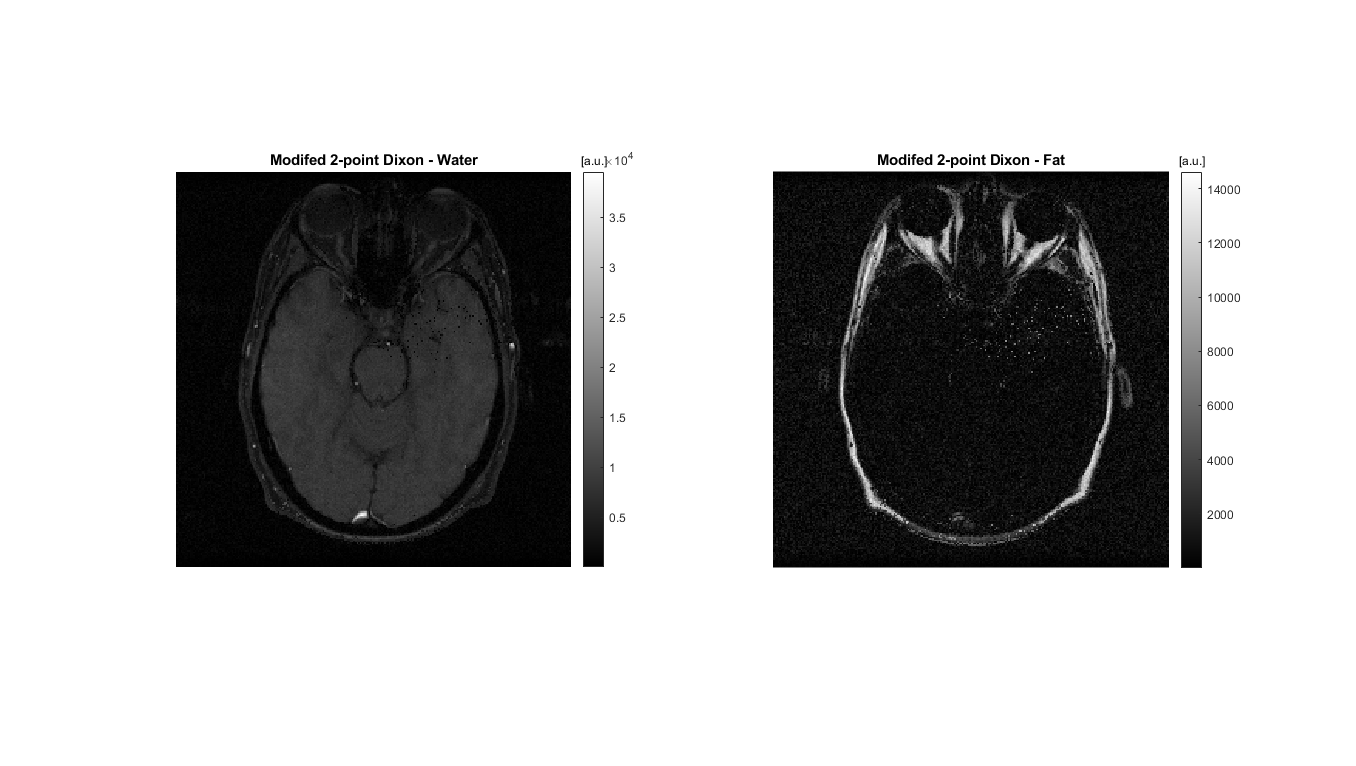

Phi_hat1 = 0.5*angle((conj(img2).*img1).^2);
Water2 = 0.5*abs((img2 + img1.*exp(-1i*Phi_hat1)));
Fat2 = 0.5*abs((img2 - img1.*exp(-1i*Phi_hat1)));
fullfig; subplot(1,2,1); imshow(Water2,[]);  title('Modifed 2-point Dixon - Water'); colorbar; map1c = colorbar; title(map1c,'[a.u.]');
subplot(1,2,2); imshow(Fat2,[]); title('Modifed 2-point Dixon - Fat'); colorbar; map2c = colorbar; title(map2c,'[a.u.]');

3-point Dixon reconstruction.

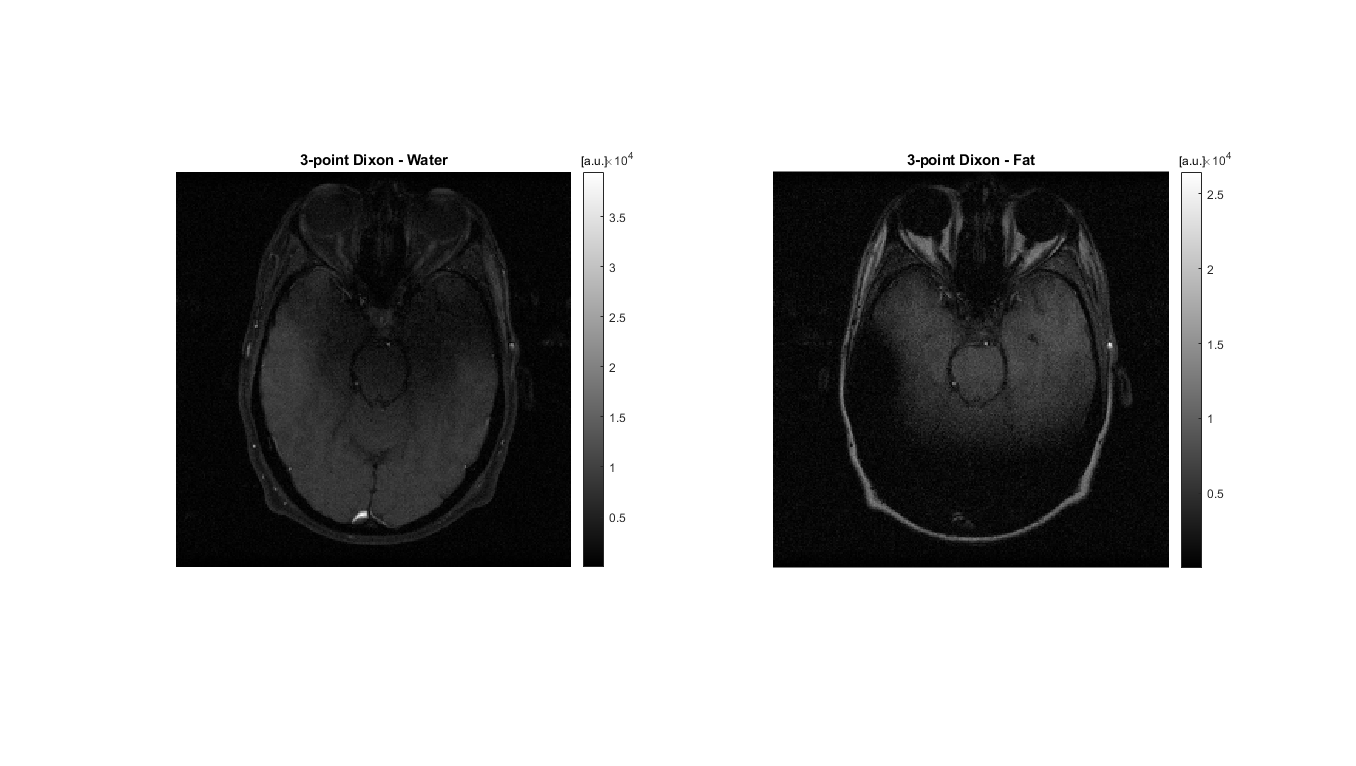

Phi_hat2 = 0.5*abs((angle(conj(img1).*img3)));
Water3 = 0.5*abs((img2 + img1.*exp(-1i*Phi_hat2)));
Fat3 = 0.5*abs((img2 - img1.*exp(-1i*Phi_hat2)));
fullfig; subplot(1,2,1); imshow(Water3,[]);  title('3-point Dixon - Water'); colorbar; map1 = colorbar; title(map1,'[a.u.]');
subplot(1,2,2); imshow(Fat3,[]); title('3-point Dixon - Fat'); colorbar; map2 = colorbar; title(map2,'[a.u.]');

Field Map Estimation

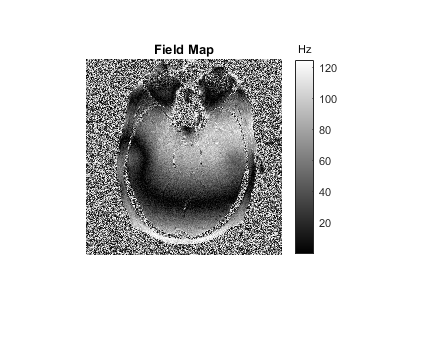

dT = 0.002;
field_map = Phi_hat2/(2*pi*dT);
fullfig; imshow(field_map,[]); title('Field Map'); colorbar; map = colorbar; title(map,'Hz');

Compare the results from d, e, and f.

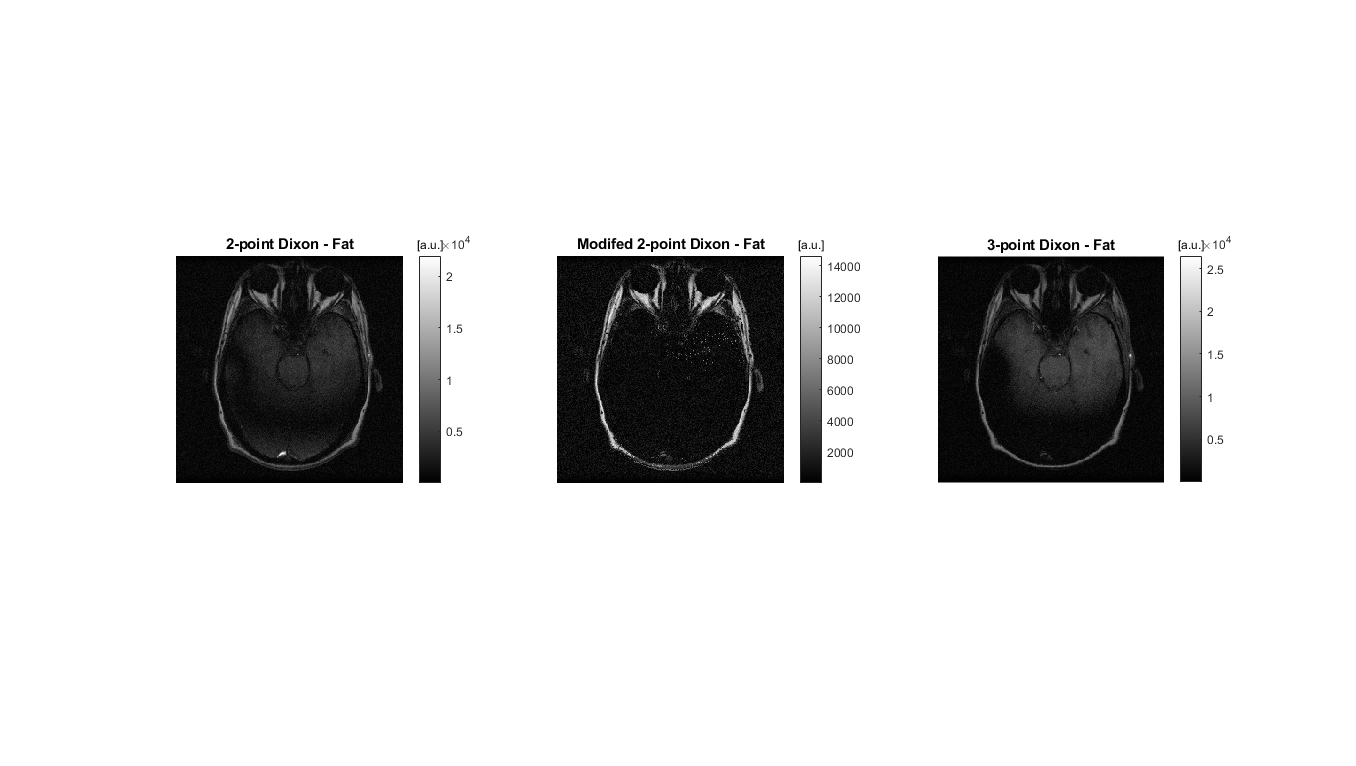

fullfig; subplot(1,3,1); imshow(Fat,[]); title('2-point Dixon - Fat'); colorbar; map2a = colorbar; title(map2a,'[a.u.]');
subplot(1,3,2); imshow(Fat2,[]);  title('Modifed 2-point Dixon - Fat'); colorbar; map2b = colorbar; title(map2b,'[a.u.]');
subplot(1,3,3); imshow(Fat3,[]); title('3-point Dixon - Fat'); colorbar; map2c = colorbar; title(map2c,'[a.u.]');

Again, the 2-point Dixon has the best delineation of fat and water. However, there are some artifacts in the middle of the brain, near the sinuses. This is expected, as this area is prone to susceptibility artifact due to the bone-air interface.

### Functions:

function value = lookup(fields,values,field, length)
    index = find(cellfun(@(s) strcmp(field, s), fields));
    value = cellfun(@str2num,values(index:(index+length-1)));
end